%Conditions
time = [0 60];
%fault at generator buses

fault = cell(16,1);
for i = 1:16
    fault{i} = {[0,0.1],i};
end


%fault at load and non-unit buses
%{
fault = cell(52,1);
for i = 1:52
    fault{i} = {[0, 0.1],i+16};
end
%}

%Note
%IEEE68bus generator11 Xls 0.0103to0.003

Simulation

net = axis1_IEEE68bus;
k = 1e-5;
 Q  = [k, 1e3, k, k,   k, k, k];           
 R  = 1e-9;
%retrofit
AGC = [zeros(5,3);-500/(2*pi*60) -10 0];
model_agc = ss(AGC);
model_agc.InputGroup.omega_agc = 1;
model_agc.InputGroup.delta_agc = 2;
model_agc.OutputGroup.u_agc = 1;
for i = 1:16
    LQR = controller_retrofit_LQR(net,i,diag(Q),diag(R));
    net.add_controller_local(LQR);
end

%AGC
con = controller_broadcast_PI_AGC(net,1:16,1:16,-10,-500);
net.add_controller_global(con);

out = net.simulate(time,...
                    'fault',     fault);

0|                                                                                                    |60
 |=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>|


calculate_l2norm(out);


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機01のl2ノルム: 0.013246
同期発電機11のl2ノルム: 0.0086557
同期発電機08のl2ノルム: 0.0066092
同期発電機09のl2ノルム: 0.0064437
同期発電機06のl2ノルム: 0.0064243
同期発電機07のl2ノルム: 0.0055892
同期発電機10のl2ノルム: 0.0055462
同期発電機05のl2ノルム: 0.0054699
同期発電機02のl2ノルム: 0.0052039
同期発電機04のl2ノルム: 0.0048886
同期発電機03のl2ノルム: 0.0048167
同期発電機12のl2ノルム: 0.0044653
同期発電機13のl2ノルム: 0.0034405
同期発電機16のl2ノルム: 0.0021019
同期発電機15のl2ノルム: 0.0012476
同期発電機14のl2ノルム: 0.0010075
 
全発電機のL２ノルムの和：0.085156


calculate_settlingtime(out);

 
最大値ピーク値は0.017507
過渡時間:周波数偏差の絶対値が0.0002以下になる時間

各発電機の周波数偏差の過渡時間(大きい順) 

同期発電機10の過渡時間: 16.8599
同期発電機01の過渡時間: 16.6665
同期発電機09の過渡時間: 13.5908
同期発電機08の過渡時間: 11.6132
同期発電機12の過渡時間: 10.5245
同期発電機02の過渡時間: 10.2639
同期発電機03の過渡時間: 8.5581
同期発電機06の過渡時間: 7.4276
同期発電機05の過渡時間: 7.3678
同期発電機07の過渡時間: 6.9635
同期発電機11の過渡時間: 5.7462
同期発電機04の過渡時間: 5.3585
同期発電機13の過渡時間: 4.8529
同期発電機14の過渡時間: 4.0484
同期発電機16の過渡時間: 3.0061
同期発電機15の過渡時間: 2.7991
 
全発電機の過渡時間の和：135.6473


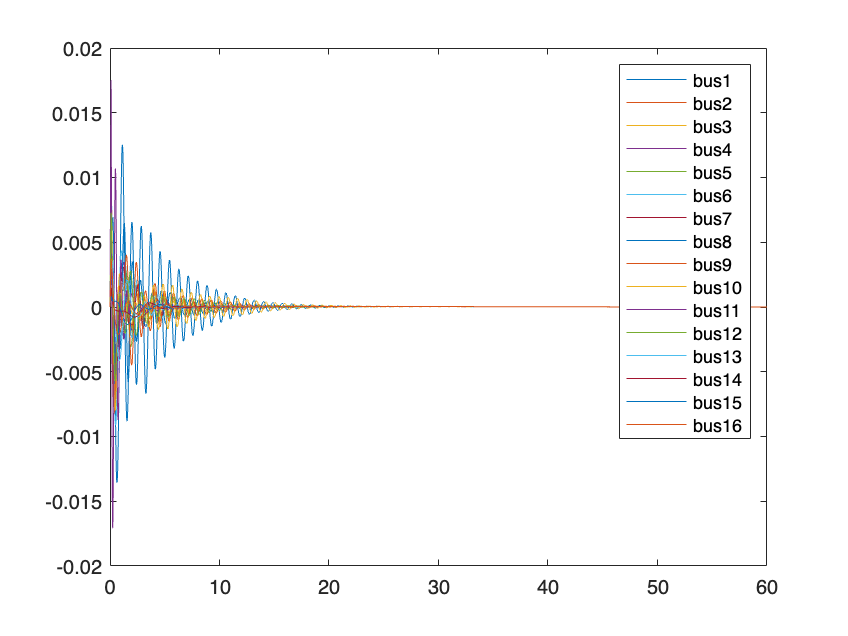

result(out);

2axis

net = axis2_IEEE68bus;

%retrofit
 k = 1e-5;
 Q  = [k, 1e3, k, k,   k, k, k,k];           
 R  = 1e-9;
n = 16;
for i = 1:n
    LQR = controller_retrofit_LQR_2axis(net,i,diag(Q),diag(R));
    net.add_controller_local(LQR);
end
 
%AGC
con = controller_broadcast_PI_AGC(net,1:n,1:n,-10,-500);
net.add_controller_global(con);


out2 = net.simulate(time,...
                    'fault',     fault);

0|                                                                                                    |60
 |=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>

=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>|




calculate_l2norm(out2);


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機01のl2ノルム: 0.010683
同期発電機11のl2ノルム: 0.0093906
同期発電機08のl2ノルム: 0.0073698
同期発電機06のl2ノルム: 0.0062079
同期発電機07のl2ノルム: 0.0059681
同期発電機05のl2ノルム: 0.0055644
同期発電機04のl2ノルム: 0.0053694
同期発電機09のl2ノルム: 0.0052229
同期発電機02のl2ノルム: 0.005108
同期発電機10のl2ノルム: 0.0050574
同期発電機03のl2ノルム: 0.0049773
同期発電機12のl2ノルム: 0.0041999
同期発電機13のl2ノルム: 0.003919
同期発電機16のl2ノルム: 0.0019077
同期発電機15のl2ノルム: 0.0014902
同期発電機14のl2ノルム: 0.0012995
 
全発電機のL２ノルムの和：0.083735


calculate_settlingtime(out2);

 
最大値ピーク値は0.017507
過渡時間:周波数偏差の絶対値が0.0002以下になる時間

各発電機の周波数偏差の過渡時間(大きい順) 

同期発電機10の過渡時間: 9.7168
同期発電機12の過渡時間: 7.9164
同期発電機01の過渡時間: 6.4961
同期発電機06の過渡時間: 6.2203
同期発電機08の過渡時間: 6.2079
同期発電機02の過渡時間: 5.4367
同期発電機09の過渡時間: 5.3832
同期発電機03の過渡時間: 5.3715
同期発電機05の過渡時間: 5.2913
同期発電機04の過渡時間: 4.8088
同期発電機07の過渡時間: 4.8071
同期発電機13の過渡時間: 4.7352
同期発電機15の過渡時間: 4.2412
同期発電機11の過渡時間: 3.9767
同期発電機16の過渡時間: 3.6204
同期発電機14の過渡時間: 3.5242
 
全発電機の過渡時間の和：87.7538


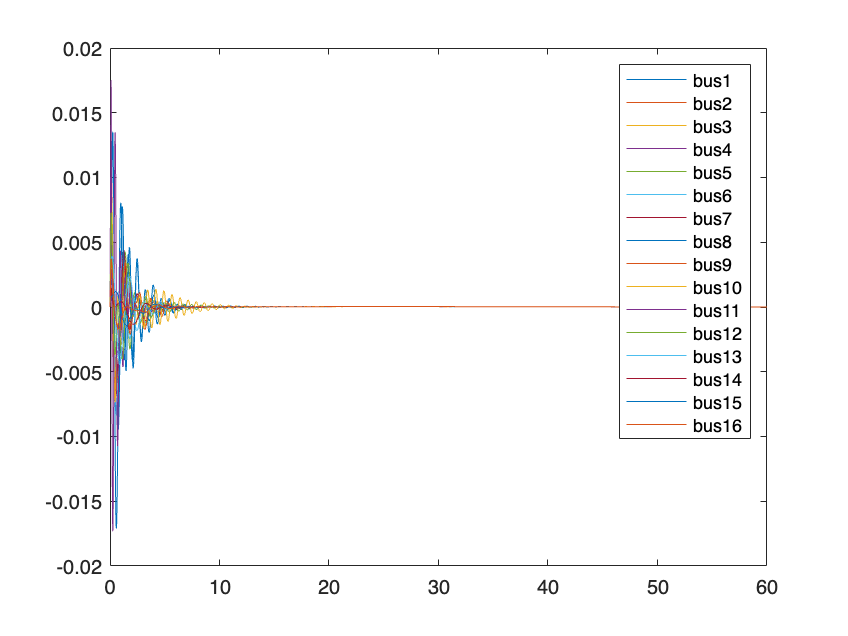

result(out2);

park

net = park_IEEE68bus;


%AGC
con = controller_broadcast_PI_AGC(net,1:16,1:16,-10,-500);
net.add_controller_global(con);

%retrofit
k = 1e-5;
 Q  = [k, 1e3, k, k,   k, k, k,k,k,k];           
 R  = 1e-9;
for i = 1:16
    LQR = controller_retrofit_LQR_PARK(net,i,diag(Q),diag(R));
    net.add_controller_local(LQR);
end

out3 = net.simulate(time,...
                    'fault',     fault);

0|                                                                                                    |60
 |=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>|



calculate_l2norm(out3);


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機11のl2ノルム: 0.012224
同期発電機01のl2ノルム: 0.011269
同期発電機08のl2ノルム: 0.0074739
同期発電機06のl2ノルム: 0.0069363
同期発電機07のl2ノルム: 0.0067923
同期発電機05のl2ノルム: 0.0062286
同期発電機04のl2ノルム: 0.0061861
同期発電機02のl2ノルム: 0.0057519
同期発電機09のl2ノルム: 0.0056977
同期発電機03のl2ノルム: 0.0055593
同期発電機10のl2ノルム: 0.0054346
同期発電機12のl2ノルム: 0.0049691
同期発電機13のl2ノルム: 0.0048703
同期発電機16のl2ノルム: 0.0022269
同期発電機15のl2ノルム: 0.0017427
同期発電機14のl2ノルム: 0.0015439
 
全発電機のL２ノルムの和：0.094906


calculate_settlingtime(out3);

 
最大値ピーク値は0.019345
過渡時間:周波数偏差の絶対値が0.0002以下になる時間

各発電機の周波数偏差の過渡時間(大きい順) 

同期発電機10の過渡時間: 8.2666
同期発電機12の過渡時間: 7.8554
同期発電機06の過渡時間: 6.218
同期発電機05の過渡時間: 6.1972
同期発電機07の過渡時間: 6.1805
同期発電機08の過渡時間: 5.9572
同期発電機01の過渡時間: 5.9278
同期発電機04の過渡時間: 5.446
同期発電機11の過渡時間: 5.4319
同期発電機02の過渡時間: 5.4305
同期発電機09の過渡時間: 5.4194
同期発電機03の過渡時間: 5.3989
同期発電機13の過渡時間: 5.2084
同期発電機14の過渡時間: 4.3432
同期発電機15の過渡時間: 4.34
同期発電機16の過渡時間: 3.6798
 
全発電機の過渡時間の和：91.3008


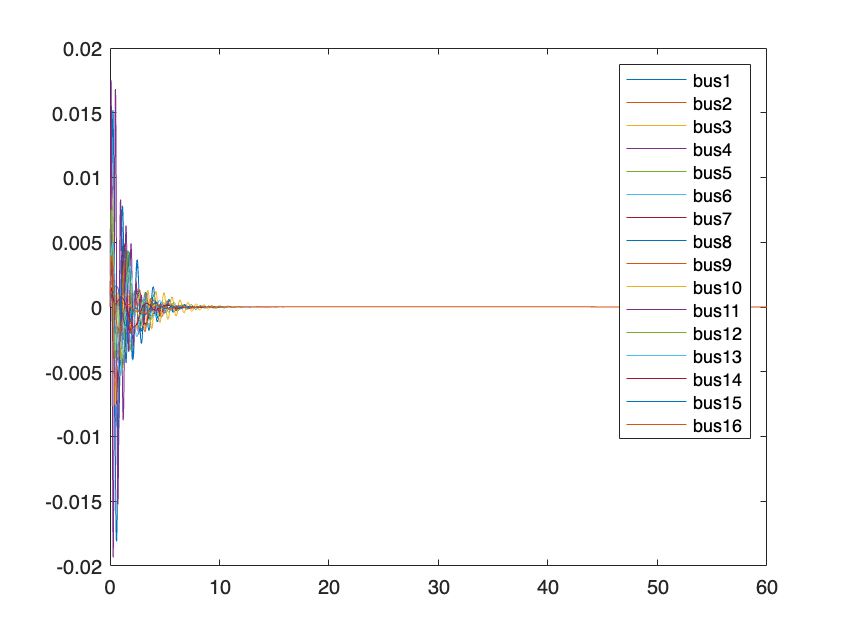

result(out3);

Test

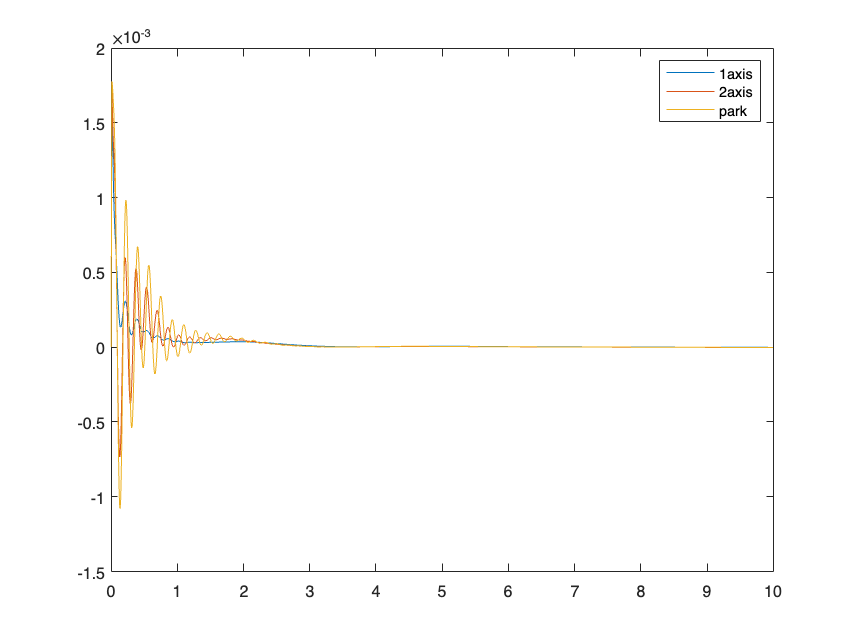

clc
plot(out.t,out.X{11}(:,2));
hold on;
plot(out2.t,out2.X{11}(:,2));
hold on;
plot(out3.t,out3.X{11}(:,2));
legend('1axis','2axis','park');

function T = calculate_settlingtime(out)
    T = zeros(1,16);
    Peak = zeros(1,16);
    for i = 1:16
        x_i = out.X{i}(:,2);
        t_i = out.t;
        info = stepinfo(x_i,t_i,0);
        Peak(i) = info.Peak;
    end
    P = max(Peak);
    clear info;


    disp(' ')
    disp(['最大値ピーク値は',num2str(P)])
    %Pを自分で設定し固定することもできる
    P = 0.005;
    error = 0.02;
    disp(['過渡時間:周波数偏差の絶対値が',num2str(P*error),'以下になる時間'])
    fprintf('\n各発電機の周波数偏差の過渡時間(大きい順) \n\n')
    for i = 1:16
        x_i = out.X{i}(:,2);
        t_i = out.t;
        %過渡時間のエラーwhich depends on each peakを統一したいのでmax Peakを使う
        info =  stepinfo(x_i,t_i,0,'SettlingTimeThreshold',P*error/Peak(i)); %定常値0
        %それぞれのピーク値からの2%エラーで収束するとする
        %info = stepinfo(x_i,t_i,0,error);
        T(i) = info.TransientTime;
        clear info;
    end
    [~, idx_sort] = sort(T,'descend');

    for i=idx_sort
        disp(['同期発電機',num2str(i,'%.2d'),'の過渡時間: ',num2str(T(i))])      
    end
    disp(' ')
    disp(['全発電機の過渡時間の和：',num2str(sum(T))])
end

function L2 = calculate_l2norm(out)
    L2 = zeros(1,16);                       %データ格納用の行列を定義
    fprintf('\n各発電機の周波数偏差のL２ノルム(大きい順) \n\n')
    for i = 1:16                            %IEEE68busは母線1~16に同期発電機が付加されている．
        omega_i  = out.X{i}(:,2);     %母線iの周波数偏差の応答データを抽出
        omega2_i = omega_i.^2;              %応答データの各要素を２乗する
        integer  = trapz(out.t, omega2_i);  %２乗したデータを数値積分する
        L2_i     = sqrt(integer);           %積分値の平方根を取りL２ノルムを計算
        L2(i)    = L2_i;                    %得られたL2ノルムを配列に格納する
    end
    [~, idx_sort] = sort(L2,'descend');     %L2ノルムの大きい順にソートした機器の番号を得る
    
    for i = idx_sort
        disp(['同期発電機',num2str(i,'%.2d'),'のl2ノルム: ',num2str(L2(i))])
    end
    disp(' ')
    disp(['全発電機のL２ノルムの和：',num2str(sum(L2))])
end

function result(out)
    leg = cell(16,1);
    for i = 1:16
        plot(out.t,out.X{i}(:,2));
        leg{i}=sprintf('bus%d',i);
        hold on;
    end
    hold off;
    legend(leg);
end
